clear; clc; close all;

projectRoot = '/Users/giuseppebonomo/Desktop/UNIPA CdLM Ing_Informatica/1 anno 2023-2024/1 Semestre 2023-2024/Metodi Numerici Avanzati/ProgettoMetodi';
addpath(genpath(projectRoot));    

% Percorso della cartella in cui salvare i risultati
this_folder = pwd;  
results_path = fullfile(this_folder, 'results');

if ~exist(results_path, 'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) Caricamento dataset
fprintf('>>> Caricamento dataset...\n');

>>> Caricamento dataset...


tic;
load('dataset/volti_dataset_Yale.mat');  % A (m×n), labels...
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.04 s



%% 2) Parametri SVD
[m, n] = size(A);
tol   = 1e-4;
maxit = 1000;

%% 3) Calcolo volto medio
fprintf('>>> Calcolo volto medio...\n');

>>> Calcolo volto medio...


tic;
mean_face = mean(A, 2);
save(fullfile(results_path, 'mean_face.mat'), 'mean_face');
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.01 s



%% 4) Centratura
fprintf('>>> Centratura dati...\n');

>>> Centratura dati...


tic;
A_centered = A - mean_face;
fprintf('   fatto in %.2f s\n', toc);

   fatto in 0.00 s



%% 5) SVD con svd_BC (artigianale)
fprintf('>>> Lancio svd_BC (tol=%.1e,maxit=%d)...\n', tol, maxit);

>>> Lancio svd_BC (tol=1.0e-04,maxit=1000)...


tic;
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=1.84 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=2.18 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=2.47 s
         [qr_eig] deflazione k=162 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=161 ... iter=550 time=1.20 s
         [qr_eig] deflazione k=160 ... iter=520 time=0.67 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=1.57 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=1.45 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=1.35 s
         [qr_eig] deflazione k=156 ... 

iter=1001 time=1.37 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=1.83 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=1.27 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.48 s
         [qr_eig] deflazione k=152 ... iter=300 time=0.56 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.49 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.47 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=1.94 s
         [qr_eig] deflazione k=148 ... iter=971 time=1.48 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=1.34 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.79 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=1.74 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.41 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.04 s
         [qr_eig] deflazione k=142 ... 

iter=1001 time=1.03 s
         [qr_eig] deflazione k=141 ... iter=148 time=0.19 s
         [qr_eig] deflazione k=140 ... 

iter=1001 time=0.77 s
         [qr_eig] deflazione k=139 ... 

iter=1001 time=0.76 s
         [qr_eig] deflazione k=138 ... iter=757 time=0.56 s
         [qr_eig] deflazione k=137 ... 

iter=1001 time=0.73 s
         [qr_eig] deflazione k=136 ... 

iter=1001 time=0.71 s
         [qr_eig] deflazione k=135 ... 

iter=1001 time=0.72 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=131 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=130 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=129 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=119 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=118 ... iter=0 time

iter=1001 time=0.45 s
         [qr_eig] deflazione k=103 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=102 ... 

iter=1001 time=0.44 s
         [qr_eig] deflazione k=101 ... 

iter=1001 time=0.43 s
         [qr_eig] deflazione k=100 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.42 s
         [qr_eig] deflazione k=98 ... 

iter=1001 time=0.40 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=95 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=94 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=93 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         

iter=1001 time=0.25 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... 

iter=1001 time=0.24 s
         [qr_eig] deflazione k=69 ... iter=143 time=0.03 s
         [qr_eig] deflazione k=68 ... iter=499 time=0.11 s
         [qr_eig] deflazione k=67 ... 

iter=1001 time=0.22 s
         [qr_eig] deflazione k=66 ... iter=430 time=0.09 s
         [qr_eig] deflazione k=65 ... iter=491 time=0.10 s
         [qr_eig] deflazione k=64 ... iter=690 time=0.14 s
         [qr_eig] deflazione k=63 ... 

iter=1001 time=0.21 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=59 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         

iter=1001 time=0.06 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=22 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=21 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=20 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=19 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=18 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=17 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=16 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=15 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=14 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=13 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=12 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=11 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=10 ... iter=0 time=0.00 s
         

iter=1001 time=0.01 s
         [qr_eig] deflazione k=4 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=483 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 43.97 s
   [svd_BC] costruisco S e U...


t_svd = toc;
fprintf('   svd_BC completata in %.2f s\n', t_svd);

   svd_BC completata in 44.04 s


save(fullfile(results_path, 'svd_data.mat'), 'U', 'S', 'V');

%% 6) Visualizzazione Eigenfaces (opzionale)
fprintf('>>> Visualizzazione risultati...\n');

>>> Visualizzazione risultati...


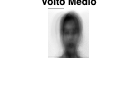

figure('Name','Volto Medio','NumberTitle','off');
imshow(reshape(mean_face,112,92), []);
title('Volto Medio');
saveas(gcf, fullfile(results_path, 'volto_medio.png'));

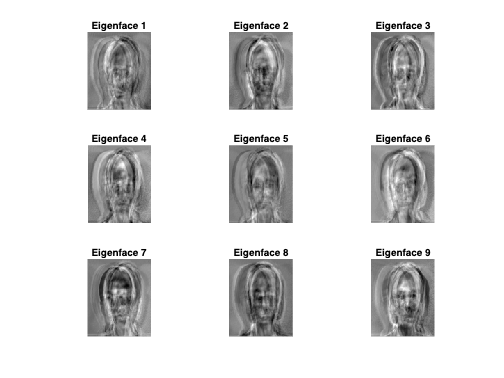


figure('Name','Prime 9 Eigenfaces','NumberTitle','off');
for i = 1:9
    subplot(3,3,i);
    imshow(reshape(U(:,i),112,92), []);
    title(sprintf('Eigenface %d', i));
end
saveas(gcf, fullfile(results_path, 'prime9_eigenfaces.png'));


fprintf('>>> Fine preprocessing (totale %.2f s)\n', sum([toc - t_svd, t_svd]));

>>> Fine preprocessing (totale 46.21 s)



%% 7) --- RETE SLP: Caricamento e preparazione dati ---
fprintf('\n=== TRAINING SLP (Single Layer Perceptron) ===\n');


=== TRAINING SLP (Single Layer Perceptron) ===


k = 100;
U_k = U(:,1:k);
A_centered = A - mean_face;
projections = U_k' * A_centered;  % [k x n]

% Split train/test
num_subjects = max(labels);
train_idx = []; test_idx = [];
for s=1:num_subjects
    idx = find(labels==s);
    idx = idx(randperm(length(idx)));
    train_idx = [train_idx, idx(1:7)];
    test_idx  = [test_idx,  idx(8:end)];
end

X_train = projections(:,train_idx)';   % [n_train x k]
y_train = labels(train_idx)';
X_test  = projections(:,test_idx)';    % [n_test  x k]
y_test  = labels(test_idx)';

% One-hot encoding
num_classes = num_subjects;
Y_train = zeros(num_classes, length(y_train));
for i=1:length(y_train)
  Y_train(y_train(i),i) = 1;
end

%% 8) Iperparametri SLP
epochs = 100;
learning_rate = 0.005;

%% 9) Addestramento SLP tramite Gradient Descent
tic;
[W, b, loss_slp] = slp_gradient_descent(X_train, Y_train, epochs, learning_rate);

[SLP] Epoch  10/100 - Loss: 4.0571
[SLP] Epoch  20/100 - Loss: 1.9644
[SLP] Epoch  30/100 - Loss: 1.1395
[SLP] Epoch  40/100 - Loss: 0.7684
[SLP] Epoch  50/100 - Loss: 0.5594
[SLP] Epoch  60/100 - Loss: 0.4319
[SLP] Epoch  70/100 - Loss: 0.3517
[SLP] Epoch  80/100 - Loss: 0.2969
[SLP] Epoch  90/100 - Loss: 0.2567
[SLP] Epoch 100/100 - Loss: 0.2254


t_slp = toc;
fprintf('SLP addestrata in %.2f s\n', t_slp);

SLP addestrata in 0.04 s



%% 10) Test SLP su test set
X_test_T = X_test';
Z_test = W * X_test_T + b;
Z_test = Z_test - max(Z_test,[],1);
expZ = exp(Z_test);
A2 = expZ ./ sum(expZ,1);
[~, y_pred_slp] = max(A2,[],1);
acc_slp = mean(y_pred_slp'==y_test)*100;
fprintf('Accuracy SLP (test set): %.2f%%\n', acc_slp);

Accuracy SLP (test set): 78.33%


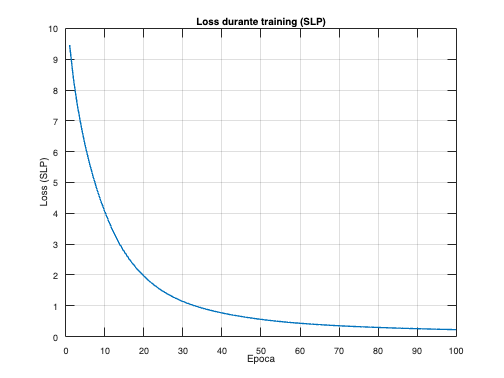


%% 11) Plot della loss
figure; 
plot(1:epochs, loss_slp, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss (SLP)');
title('Loss durante training (SLP)');
grid on;